% Clear variables, figures
clear;
clf;
clc;

% Human arm parameters
run('human_arm_param.m');

% Marker is placed in the : shoulder --> 1
%                           forearm  --> 2
%                           hand     --> 3
marker.links = [1;
                1;
                1;
                1;
                2;
                2;
                2;
                3;
                3];
marker.shoulder_variables = [arm.shoulder.radius+arm.markers.radius -3/4*arm.shoulder.length 0;
                   -arm.shoulder.radius-arm.markers.radius -3/4*arm.shoulder.length 0;
                   arm.shoulder.radius+arm.markers.radius -1/4*arm.shoulder.length 0;
                   -arm.shoulder.radius-arm.markers.radius -1/4*arm.shoulder.length 0]';
marker.forearm_variables = [arm.forearm.radius+arm.markers.radius -3/4*arm.forearm.length 0;
                   -arm.forearm.radius-arm.markers.radius -1/2*arm.forearm.length 0;
                   arm.forearm.radius+arm.markers.radius -1/4*arm.forearm.length 0]';
marker.hand_variables = [0 -3/4*arm.hand.dimensions(2) arm.hand.dimensions(3)/2+arm.markers.radius;
                   0 -1/4*arm.hand.dimensions(2) arm.hand.dimensions(3)/2+arm.markers.radius]';

% Number of markers
m = size(marker.links, 1);

% Noise
noise.sampleTime = 0.01;
noise.p_var = 0.00001 * ones(m * 3, 1);
noise.p_seed = 1;
noise.pdot_seed = 2;

% Run Phi_J_generation
run('master_thesis_script.m');

Building with 'gcc'.
MEX completed successfully.
Building with 'gcc'.
MEX completed successfully.
Building with 'gcc'.
MEX completed successfully.
Building with 'gcc'.
MEX completed successfully.


% Open Simulink model
open('master_thesis_simulink.slx');

# LS APPROACH


$$\dot{q} = J^{\dagger}(q) \cdot  u  \qquad \longrightarrow \qquad u = \dot{p}$$


#### FORWARD KINEMATICS


$$\pmatrix{p_{1} \cr P_{2} \cr .. \cr P_{M}} = \pmatrix{\Phi_1(q) \cr \Phi_2(q) \cr ..  \cr \Phi_M(q) } \qquad \Longrightarrow \qquad  p = \Phi(q)$$


#### JACOBIAN COMPUTATION


$$\pmatrix{\dot{p}_{1} \cr \dot{p}_{2} \cr .. \cr \dot{p}_{M}} = \pmatrix{J_1(q) \cr J_2(q) \cr ..  \cr J_M(q) } \cdot \dot{q} \qquad \Longrightarrow \qquad  \dot{p} = J(q) \cdot  \dot{q} $$


## 1.  PERFECT GUESS OF INITIAL CONDITION q0 

% Initial CORRECT joint variables estimate used by LS
LS.q0 = [0;
         0;
         0;
         0;
         0;
         0;
         0];

###       1.1 SMALLER NOISE vs LARGER NOISE affecting pdot

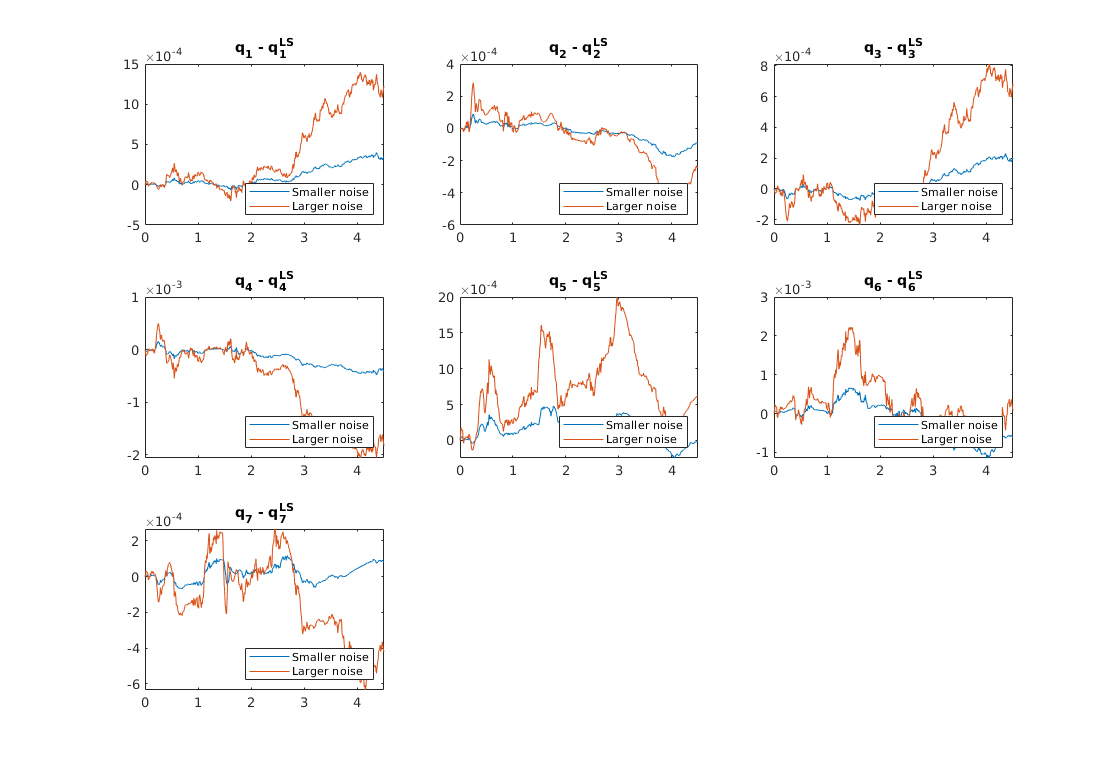

% Noise affecting pdot measurements
noise.pdot_var = 0.0000001 * ones(m * 3, 1);
% Simulation
output_1 = sim("master_thesis_simulink.slx");

% Noise affecting pdot measurements
noise.pdot_var = 0.000001 * ones(m * 3, 1);
% Simulation
output_2 = sim("master_thesis_simulink.slx");

% Plot error between q_LS and q (comparison between smaller noise and larger noise)
title_name = cell(n, 1);
fig_1 = figure(1);
for i = 1 : n

    title_name{i} = strcat('q_', num2str(i), ' - q_', num2str(i), '^{LS}');
    set(fig_1, 'position', [10, 10, 1300, 900]);
    subplot(3,3,i);
    plot(output_1.q.time, output_1.q.signals.values(:, i) - squeeze(output_1.q_LS.signals.values(i, :))');
    hold on;
    plot(output_2.q.time, output_2.q.signals.values(:, i) - squeeze(output_2.q_LS.signals.values(i, :))');
    legend('Smaller noise', 'Larger noise', 'Location', 'southeast');
    title(title_name{i});
end

## 2.  WRONG GUESS OF INITIAL CONDITION q0

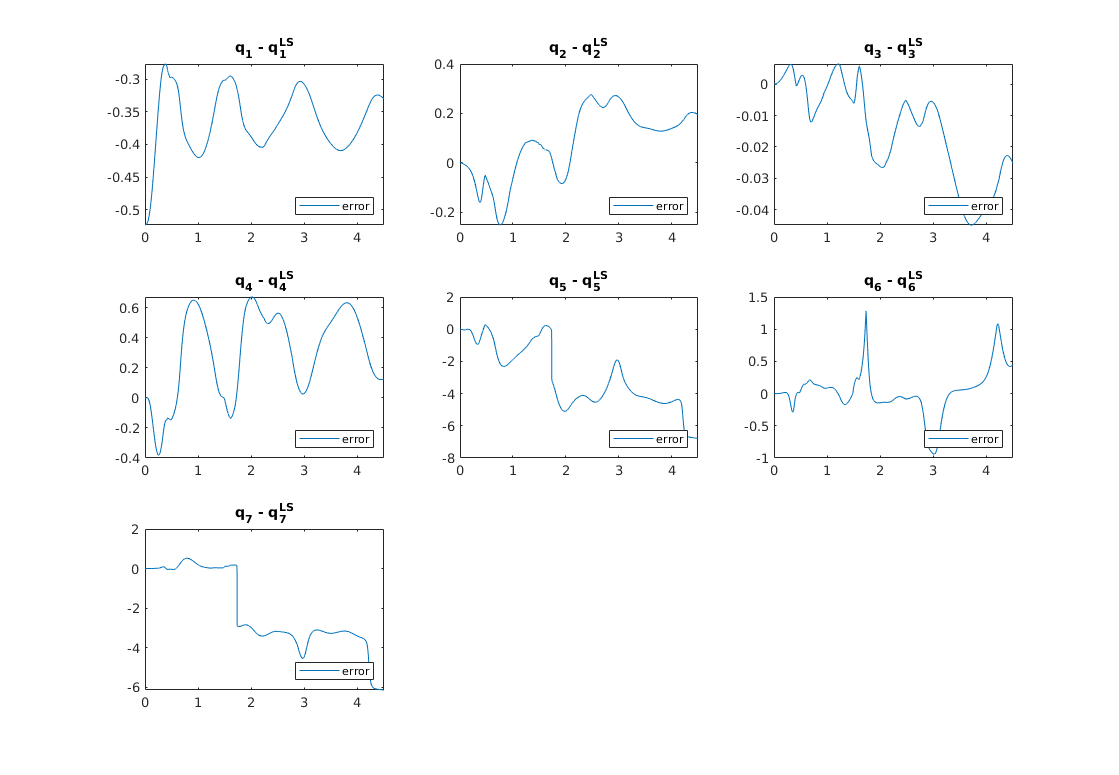

% Initial WRONG joint variables estimate used by LS
LS.q0 = [pi/6;
         0;
         0;
         0;
         0;
         0;
         0];

% Noise affecting pdot measurements
noise.pdot_var = 0.0000001 * ones(m * 3, 1);

% Simulation
output_3 = sim("master_thesis_simulink.slx");

% Plot error between q_LS and q
fig_3 = figure(3);
for i = 1 : n

    title_name{i} = strcat('q_', num2str(i), ' - q_', num2str(i), '^{LS}');
    set(fig_3, 'position', [10, 10, 1300, 900]);
    subplot(3,3,i);
    plot(output_3.q.time, output_3.q.signals.values(:, i) - squeeze(output_3.q_LS.signals.values(i, :))');
    legend('error', 'Location', 'southeast');
    title(title_name{i});
end

#### DISCRETE NON LINEAR MODEL (Ts = 1ms)


$$q_{k+1} = q_k + \frac{1}{6}  \cdot T_s  \cdot (k_1 + 2k_2 + 2k_3 + k_4)  \\
p_k = \Phi(q_k) \\
\\
\\
k_1 = J^{\dagger}(q_k)\cdot u_k  \\
k_2 = J^{\dagger}(q_k + T_s  \cdot  \frac{k_1}{2})\cdot u_k  \\
k_3 = J^{\dagger}(q_k + T_s  \cdot  \frac{k_2}{2})\cdot u_k  \\
k_4 = J^{\dagger}(q_k + T_s  \cdot  k_3)\cdot u_k$$


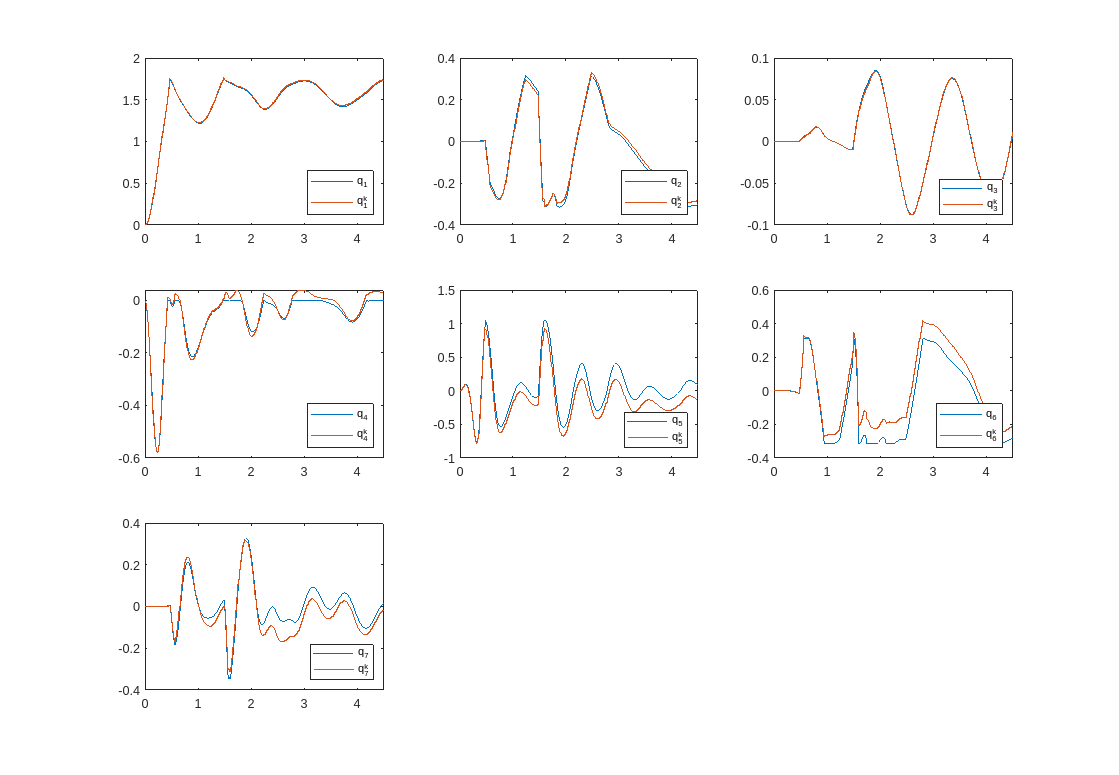

sample_Time = 0.01;
% Simulation
output_4 = sim("master_thesis_simulink.slx");

% Plot DISCRETE vs CONTINUOS joints' variables (q vs qk)
fig_4 = figure(4);
for i = 1 : n

    q = strcat('q_', num2str(i));
    qk = strcat('q^k_', num2str(i));
    set(fig_4, 'position', [10, 10, 1300, 900]);
    subplot(3,3,i);
    plot(output_4.q.time, output_4.q.signals.values(:, i));
    hold on;
    stairs(output_4.qk.time, squeeze(output_4.qk.signals.values(i, :))');
    legend(q, qk, 'Location', 'southeast');
end